clear;
clc;
%N=total number of points or samples
%n=vector of integer number from 0-N-1
%fs=Frequency of sampling or number of samples
%t=vector of time
%TTime Total Time
%x=vectpr pf signal amplitude
%Tx=period of a signal "x"
%fx=Frequency of a signal "x"
%wx=frequency of a signal "x"
%Tau=Delay of step function
N=1000;
dt=0.001;
TTime=dt*(N-1);
fs=1/dt;
n=0:1:(N-1);
t=n*dt;
x=3*sin(2*pi*(20)*t)

x =          0    0.3760    0.7461    1.1044    1.4453    1.7634    2.0536    2.3115    2.5330    2.7145    2.8532    2.9469    2.9941    2.9941    2.9469    2.8532    2.7145    2.5330    2.3115    2.0536    1.7634    1.4453    1.1044    0.7461    0.3760    0.0000   -0.3760   -0.7461   -1.1044   -1.4453   -1.7634   -2.0536   -2.3115   -2.5330   -2.7145   -2.8532   -2.9469   -2.9941   -2.9941   -2.9469   -2.8532   -2.7145   -2.5330   -2.3115   -2.0536   -1.7634   -1.4453   -1.1044   -0.7461   -0.3760


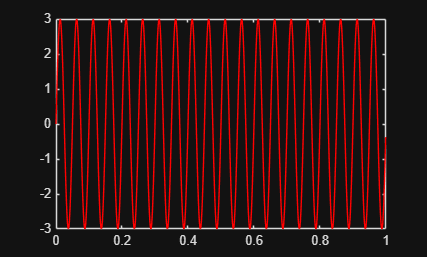

plot (t,x, "r");

title = ("Amplitude vs time(s)")

title = "Amplitude vs time(s)"

xlabel = ("Time(s)")

xlabel = "Time(s)"

ylabel = ("Amplitude")

ylabel = "Amplitude"

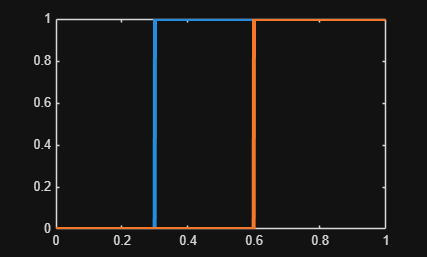

N = 1000;
dt = 0.001;
n = 0:(N-1);
t = n*dt;

t0 = 0.3;          % step time (seconds)
t1 = 0.6;
A1 = 1;            % step amplitude
A2 = 1;
x1 = A1 * (t >= t0); % unit step scaled by A
x2 = A2 * (t >= t1);
plot(t, x1, t, x2, 'LineWidth', 3)

%xlabel('Time (s)')
%ylabel('Amplitude')
%title('Step Function')
%grid on



N = 1000;
dt = 0.001;
n = 0:(N-1);
t = n * dt;

t0 = 0.3;
t1 = 0.6;
A1 = 1;
A2 = 1;

x1 = A1 * (t >= t0);   % step ON
x2 = A2 * (t >= t1);   % step OFF

pulse = x1 - x2;       % rectangular pulse

% plot(t, pulse, 'LineWidth', 3)
% xlabel('Time (s)')
% ylabel('Amplitude')
% title('Rectangular Pulse')
% ylim([-0.2 1.2])
% grid on



e=exp(-5*t)

e =     1.0000    0.9950    0.9900    0.9851    0.9802    0.9753    0.9704    0.9656    0.9608    0.9560    0.9512    0.9465    0.9418    0.9371    0.9324    0.9277    0.9231    0.9185    0.9139    0.9094    0.9048    0.9003    0.8958    0.8914    0.8869    0.8825    0.8781    0.8737    0.8694    0.8650    0.8607    0.8564    0.8521    0.8479    0.8437    0.8395    0.8353    0.8311    0.8270    0.8228    0.8187    0.8146    0.8106    0.8065    0.8025    0.7985    0.7945    0.7906    0.7866    0.7827


p= pulse .*(x)

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


z= x.*e

z =          0    0.3741    0.7386    1.0879    1.4166    1.7198    1.9929    2.2320    2.4337    2.5950    2.7140    2.7892    2.8197    2.8057    2.7476    2.6470    2.5058    2.3266    2.1126    1.8675    1.5956    1.3012    0.9893    0.6650    0.3335    0.0000   -0.3302   -0.6519   -0.9601   -1.2502   -1.5177   -1.7588   -1.9698   -2.1477   -2.2901   -2.3951   -2.4614   -2.4884   -2.4760   -2.4248   -2.3360   -2.2113   -2.0532   -1.8644   -1.6481   -1.4081   -1.1483   -0.8731   -0.5869   -0.2943


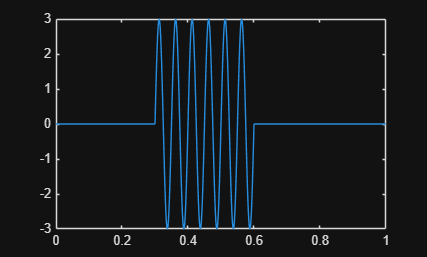


plot(t,p)

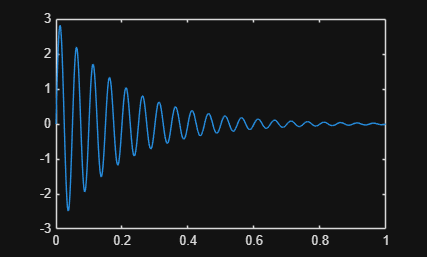

plot(t,z)